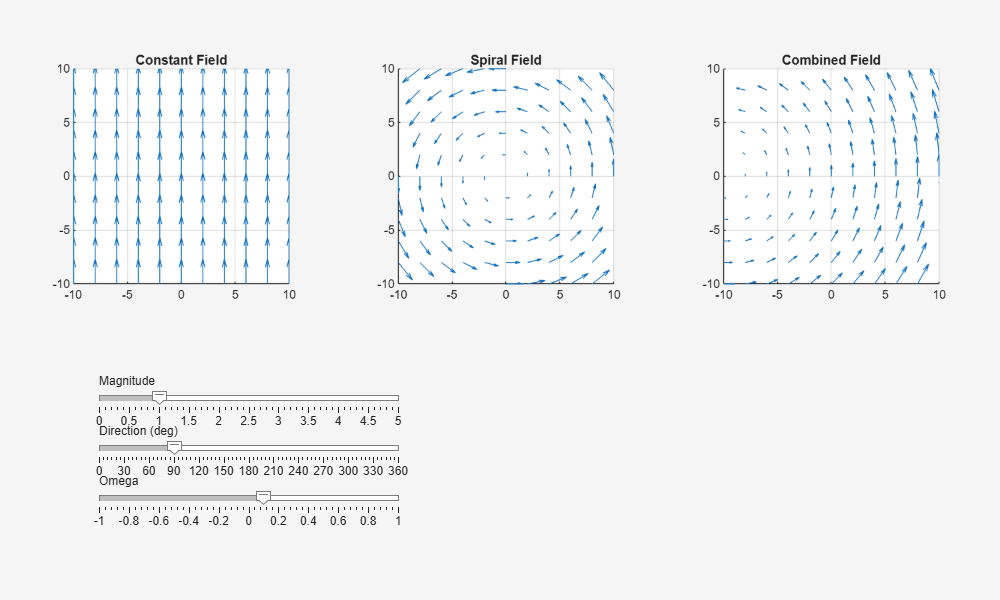

% Create UI figure
fig = uifigure('Name','Vector Field Control','Position',[100 100 1000 600]);

% Axes
ax1 = uiaxes(fig,'Position',[50 300 250 250]);
ax2 = uiaxes(fig,'Position',[375 300 250 250]);
ax3 = uiaxes(fig,'Position',[700 300 250 250]);

% Controls
sMag = uislider(fig,'Position',[100 200 300 3],'Limits',[0 5],'Value',1);
sDir = uislider(fig,'Position',[100 150 300 3],'Limits',[0 360],'Value',90);
sOmega = uislider(fig,'Position',[100 100 300 3],'Limits',[-1 1],'Value',0.1);

% Labels
uilabel(fig,'Position',[100 210 100 20],'Text','Magnitude');
uilabel(fig,'Position',[100 160 100 20],'Text','Direction (deg)');
uilabel(fig,'Position',[100 110 100 20],'Text','Omega');

% Grid
[x, y] = meshgrid(-10:2:10, -10:2:10);

% Loop
while isvalid(fig)
    
    % Read inputs
    M = sMag.Value;
    theta = deg2rad(sDir.Value); % convert to radians
    omega = sOmega.Value;
    
    % Constant field (from magnitude + direction)
    u = M * cos(theta) * ones(size(x));
    v = M * sin(theta) * ones(size(y));
    
    % Spiral field
    u2 = -omega * y;
    v2 =  omega * x;
    
    % Combined field
    u3 = u + u2;
    v3 = v + v2;
    
    % --- Plot 1 ---
    cla(ax1);
    quiver(ax1, x, y, u, v);
    title(ax1,'Constant Field');
    axis(ax1,'equal');
    xlim(ax1,[-10 10]); ylim(ax1,[-10 10]);
    grid(ax1,'on');
    
    % --- Plot 2 ---
    cla(ax2);
    quiver(ax2, x, y, u2, v2);
    title(ax2,'Spiral Field');
    axis(ax2,'equal');
    xlim(ax2,[-10 10]); ylim(ax2,[-10 10]);
    grid(ax2,'on');
    
    % --- Plot 3 ---
    cla(ax3);
    quiver(ax3, x, y, u3, v3);
    title(ax3,'Combined Field');
    axis(ax3,'equal');
    xlim(ax3,[-10 10]); ylim(ax3,[-10 10]);
    grid(ax3,'on');
    
    drawnow;
end